# **Metabolic Systems Biotechnology  Project**

## Diego Alba Burbano

## Part 1: Simulating the wild type maximum growth rate of *E. coli *under different conditions

Load the data from the provided files:

S = xlsread('ecoli_core_model(2).xlsx',1,'B2:BZ64');
lb = xlsread('ecoli_core_model(2).xlsx',2,'B2:B78');
ub = xlsread('ecoli_core_model(2).xlsx',2,'C2:C78');

Specify variables to keep track of the differet simulating conditions:

substrate = [69 72 76 64 69 72 76 64];
uptake_rates = [10 18 12 12 10 18 12 12];
aerobic = [20 20 20 20 0 0 0 0];

lb(65) = -1000; % to make sure CO2 is available
lb(substrate) = 0; % to make sure only one substrate is available

Run the differnet simulations maximizing the two reactions; if no solution is found set to NaN. Show the resulting fluxes.

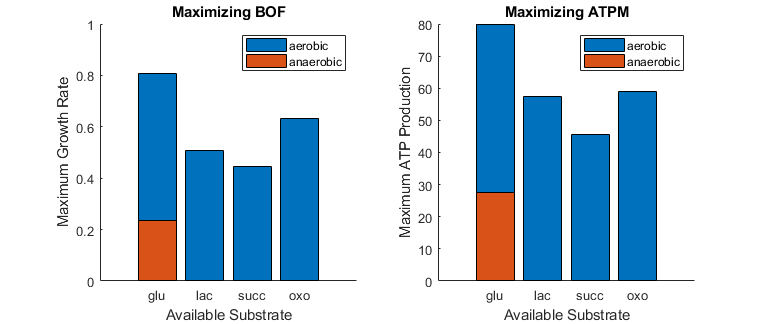

for i = 1:length(substrate)
    % metabolic_opti() is a custom fuction defined at the end of the file
    v_bof = metabolic_opti(S,lb,ub,substrate(i),uptake_rates(i),aerobic(i),77,[],-1);
    v_atpm = metabolic_opti(S,lb,ub,substrate(i),uptake_rates(i),aerobic(i),8,[],-1);
    
    if ~isempty(v_bof); all_bof(i) = v_bof(77); else all_bof(i) = NaN; end
    if ~isempty(v_atpm); all_atpm(i) = v_atpm(8); else all_atpm(i) = NaN; end
end
bofSim1= all_bof;
figure; set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.4, 0.3]);
subplot(1,2,1); hold on
bar(all_bof(1:4)); bar(all_bof(5:end))
xlabel('Available Substrate'); ylabel('Maximum Growth Rate'); title('Maximizing BOF')
xticks(1:4); xticklabels({'glu','lac','succ','oxo'})
legend('aerobic','anaerobic')

subplot(1,2,2); hold on
bar(all_atpm(1:4)); bar(all_atpm(5:end))
xlabel('Available Substrate'); ylabel('Maximum ATP Production'); title('Maximizing ATPM')
xticks(1:4); xticklabels({'glu','lac','succ','oxo'})
legend('aerobic','anaerobic')

We can aprreciate that under anaerobic conditions and subtrates other than glucose, there exists no solution.

There is also a geat reduction in both BOF and ATPM when there is no oxygen.

Correlation between maximizing the two reactions:

correaltion = corr2(all_bof(1:5),all_atpm(1:5)) % excluding NaN values

correaltion = 0.9832

Such a high and positive correlation suggests that maximizing either reactions will also produce high fluxes in the other.

In other words, it takes energy (ATP) to grow. 

Summary table:

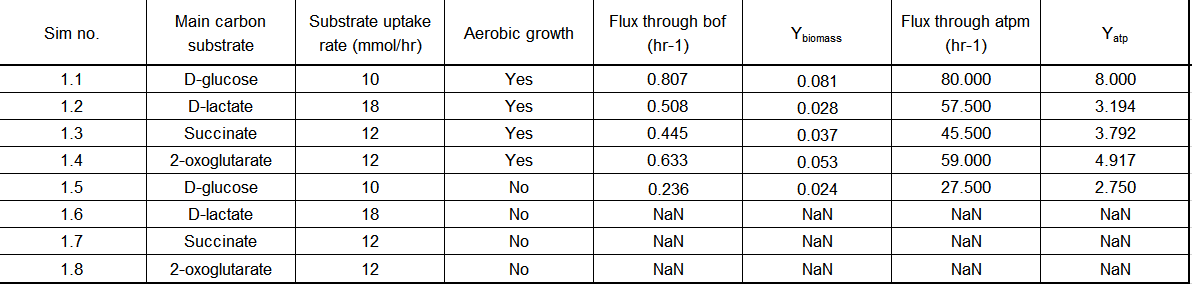

## Investigating why some solutions were not found

We specified a lower bound for the production of ATP. Meaning that we do not consider solutions that produce less than that ATP.

minimum_atp = lb(8)

minimum_atp = 8

Because of the dramatic reduction in ATP production when oxygen is absent and glucose is the only substrate, we can hypothesize that for the other subtrates we will see a similar trend. We remove this constrain to test it.

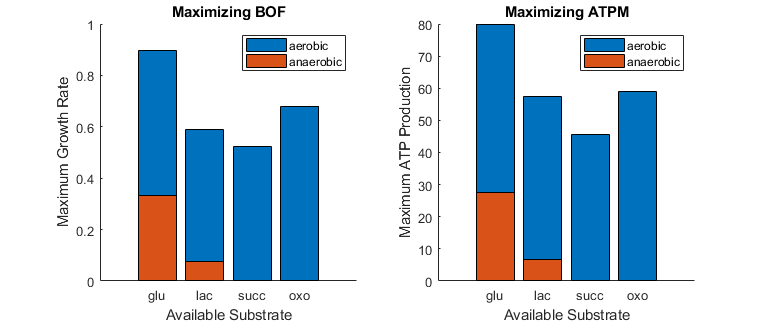

lb(8) = 0;

for i = 1:length(substrate)
    % metabolic_opti() is a custom fuction defined at the end of the file
    v_bof = metabolic_opti(S,lb,ub,substrate(i),uptake_rates(i),aerobic(i),77,[],-1);
    v_atpm = metabolic_opti(S,lb,ub,substrate(i),uptake_rates(i),aerobic(i),8,[],-1);
    
    all_bof(i) = v_bof(77); all_atpm(i) = v_atpm(8);
end

figure; set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.4, 0.3]);
subplot(1,2,1); hold on
bar(all_bof(1:4)); bar(all_bof(5:end))
xlabel('Available Substrate'); ylabel('Maximum Growth Rate'); title('Maximizing BOF')
xticks(1:4); xticklabels({'glu','lac','succ','oxo'})
legend('aerobic','anaerobic')

subplot(1,2,2); hold on
bar(all_atpm(1:4)); bar(all_atpm(5:end))
xlabel('Available Substrate'); ylabel('Maximum ATP Production'); title('Maximizing ATPM')
xticks(1:4); xticklabels({'glu','lac','succ','oxo'})
legend('aerobic','anaerobic')

Now we can observe how lac, succ, and oxo produce little to no ATP (6.75, 0, and 0 respectivly), which explains why didn't find a solution in our previous analysis.

Moreover, we can observe the effect of oxygen deplition on ATP production and cell growth rate if we run simulation at different oxygen uptake rates.

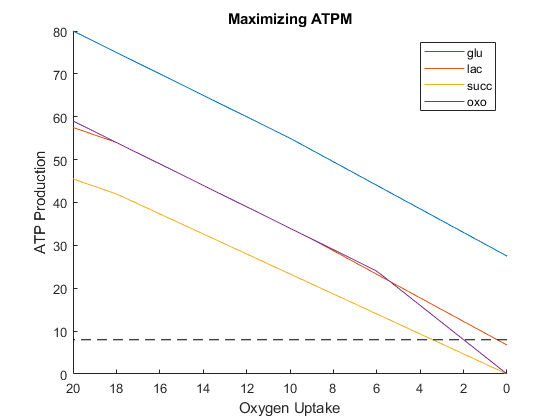

substrate = [69 72 76 64];
uptake_rates = [10 18 12 12];
oxygen = linspace(20,0);

for j = 1:length(oxygen)
    for i = 1:length(substrate)
        % metabolic_opti() is a custom fuction defined at the end of the file
        v_atpm = metabolic_opti(S,lb,ub,substrate(i),uptake_rates(i),oxygen(j),8,[],-1);
        
        all_atpm_od(i,j) = v_atpm(8);
    end
end

figure; hold on
set(gca, 'Xdir', 'reverse')
plot(oxygen,all_atpm_od)
plot([0 20],[8 8],'k--')
xlabel('Oxygen Uptake'); ylabel('ATP Production'); title('Maximizing ATPM')
legend('glu','lac','succ','oxo')

We can observe that the only solution above the 8 ATP threshold is indeed when glucose is the only substrate. There is a minimal oxygen uptake rate needed to reach at least 8 ATP with other substrates rather than glucose.

Biologically, this is explained by the fact that oxygen deplition limits the electron transport chain (which produces the vast majority of ATP) and in turn the TCA cycle, which involves the lac, succ, and oxo. In contrast, glucose is still consumed through glycolisis and some ATP can be produced even in the absence of oxygen.

## Part 2: Simulating the maximum groth rate of *E. coli* for different genetic mutations

Load the protein data (will serve to modify specific reactions).

% vector with proteins involved for each reaction
[~,proteins] = xlsread('ecoli_core_model(2).xlsx',3,'E2:E78');
proteins = cellfun(@(proteins) strsplit(proteins,'+'),proteins, 'UniformOutput',false);

Create vectors for substrate, uptake rates, and mutation:

substrate = [69 72 64 69 64 69 72 69 72]; lb(8)=8;
uptake_rates = [10 18 12 10 12 10 18 10 18];
aerobic = 20*ones(1,9);
mutation = {{'AcnB, AcnA'};
    {'AcnB, AcnA'};
    {'AcnB, AcnA'};
    {'Pck'};
    {'Pck'};
    {'Tpi'};
    {'Tpi'};
    {'AtpF0'};
    {'AtpF0'}};

 Check which reactions were mutated:

index = cellfun(@(mutation) cellfun(@(proteins)...
    sum(contains(proteins,mutation)),proteins),mutation,'UniformOutput',false);

index = cellfun(@(index) find(index),index);

Optimize BOF for each set of conditions:

for i = 1:length(substrate)
    % metabolic_opti() is a custom fuction defined at the end of the file
    v_bof = metabolic_opti(S,lb,ub,substrate(i),uptake_rates(i),aerobic(i),77,index(i),-1);
    
    all_bof(i) = v_bof(77);
end

Summary table with optimization results:

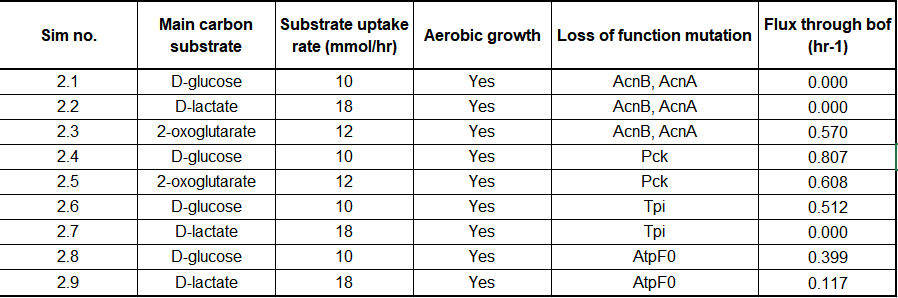

Explanation:

We observe a complete reduction of BOF flux in simulations 2.1 and 2.2 because a loss of function in AcnB and AcnA means that citrate in the TCA cycle cannot be converted into isocitrate, and viceversa. When glucose or lactate are the only available carbon susbtrate, phosphoenolpyruvate and acetyl-CoA enter the TCA cycle by being converted into oxaloactetate and citrate, respectivly. However they will not go through the cycle due to the lack of aconitase, acuumulating citrate and producing no ATP or cell growth. This is not the case in 2.3, when 2-oxoglutarate is available, since the substrate can go through the TCA cycle without being converted into citrate, and therefore producing ATP and allowing for cell growth.

## Part 3: Simulation of alterate fluxes for maximal growth rate of wild *E. coli *using FVA

Corresponding reaction to D and A: 4 and 1 (ADHEr and ACKr).

Simulating conditions from Part 1.1:

substrate = 69; uptake = 10; aerobic = 20; lb(end) = bofSim1(1); ub(end) = bofSim1(1);

FVA:

rxns = [10,4,1,8]; % Reaction 4 for D and reaction 1 for A

for i = 1:length(rxns)
    % metabolic_opti() is a custom fuction defined at the end of the file
    v_bof = metabolic_opti(S,lb,ub,substrate,uptake,aerobic,rxns(i),[],-1);
    if ~isempty(v_bof); crange(i,1) = v_bof(rxns(i)); else crange(i,1) = NaN; end
    v_bof = metabolic_opti(S,lb,ub,substrate,uptake,aerobic,rxns(i),[],1);
    if ~isempty(v_bof); crange(i,2) = v_bof(rxns(i)); else crange(i,2) = NaN; end
end

The range for the reactions:

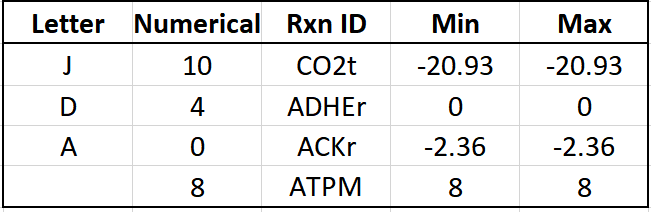

To find ranges at 75% of maximum BOF:

lb(end) = 0.75*bofSim1(1); ub(end) = 0.75*bofSim1(1);

for i = 1:length(rxns)
    % metabolic_opti() is a custom fuction defined at the end of the file
    v_bof = metabolic_opti(S,lb,ub,substrate,uptake,aerobic,rxns(i),[],-1);
    if ~isempty(v_bof); crange(i,1) = v_bof(rxns(i)); else crange(i,1) = NaN; end
    v_bof = metabolic_opti(S,lb,ub,substrate,uptake,aerobic,rxns(i),[],1);
    if ~isempty(v_bof); crange(i,2) = v_bof(rxns(i)); else crange(i,2) = NaN; end
end

crange =    -6.7683  -25.2147
    6.6772         0
         0  -10.8016
   26.0000    8.0000


The range for the reactions at 75% BOF:

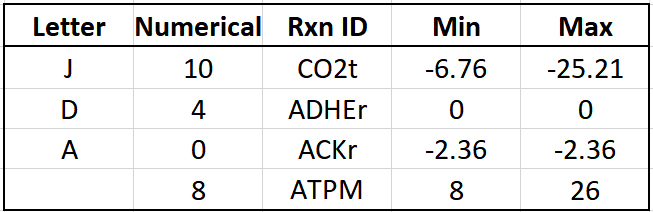

We can observe there is no change on the min ATPM reaction. However, there is a considerable increase in the maximum ATP production: from 8  to 26, or 225% increase. 

## metabolic_opti

Create a support function that will take the simulation conditions and run *linprog:*

function v = metabolic_opti(S,lb,ub,substrate,uptake,aerobic,reaction,mutation,w)
dxdt = zeros(size(S,1),1);

lb(substrate) = -uptake; % set to the specified upate rate
lb(73) = -aerobic; % set weather aerobic (uptake of 20) or anaerobic (uptake of 0)

% pick reaction to optimize (bof ot atpm)
weights = zeros(1,size(S,2)); weights(reaction) = w;

% muation
lb(mutation) = 0;
ub(mutation) = 0;

v = linprog(weights,[],[],S,dxdt,lb,ub,optimset('Display','off'));
end